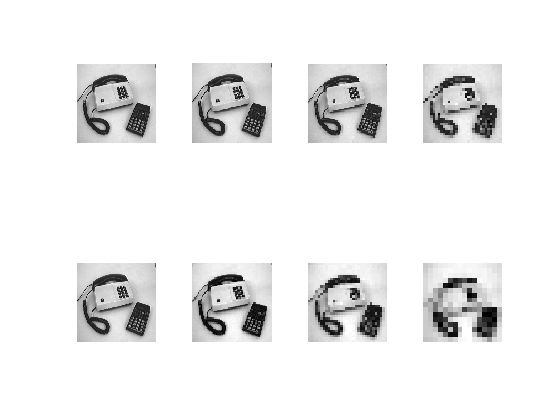

clear

img=phonecalc256;
smoothimg=img;
N=4;
for i=1:N
    if i>1
        img=rawsubsample(img);
        smoothimg=gaussfft(img,1.0);
        smoothimg=rawsubsample(smoothimg);
    end
    subplot(2,N,i)
    showgrey(img)
    subplot(2,N,i+N)
   showgrey(smoothimg);
end

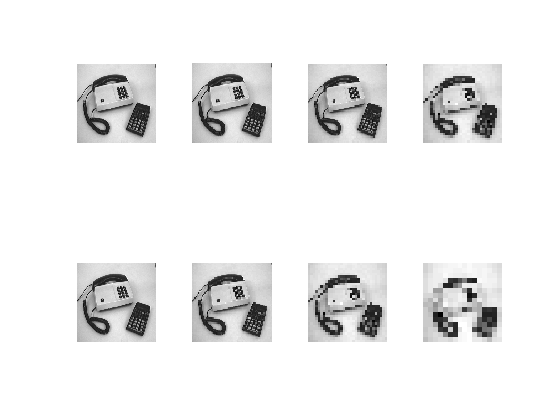


figure
img=phonecalc256;
smoothimg=img;
for i=1:N
    if i>1
        img=rawsubsample(img);
        smoothimg=ideal(img,1.0);
        smoothimg=rawsubsample(smoothimg);
    end
    subplot(2,N,i)
    showgrey(img)
    subplot(2,N,i+N)
   showgrey(smoothimg)end